# Custom functions

function r = gen_points_RS(RBV)
    r = [];
    for i = 1:10000
        k1 = -1 + 2*rand(1);
        k2 = -1 + 2*rand(1);
        r = [r,k1*RBV(1,:)'+k2*RBV(2,:)'];
    end
end

function r = gen_points_CS(CSV)
    r = [];
    for i = 1:10000
        k1 = -1 + 2*rand(1);
        k2 = -1 + 2*rand(1);
        r = [r,k1*CSV(:,1)+k2*CSV(:,2)];
    end
end

function r = Check_subspace(A,y)
    if(rank([A,y]) == rank(A))
        fprintf("This lies in column space")
    elseif(rank([A;(y')]) == rank(A))
        fprintf("This lies in row space")
    elseif(A*y == 0)
        fprintf("This lies in null space")
    else
        fprintf("This does not lie in a subspace")
    end
end

## Q1

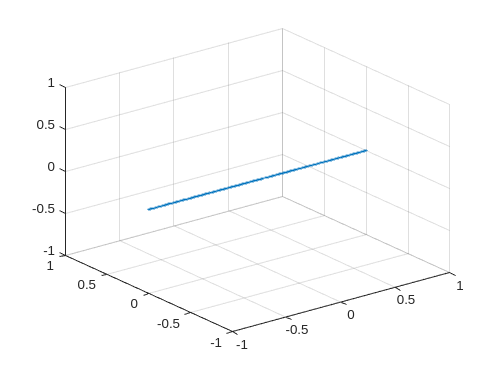


M = [1 0 0;0 0 0;0 0 3];
[RR, ic] = rref(M);
RBV = M(1:length(ic),:);
N = null(M);
RSpts = [];
NSpts = [];
for i = 1:1000
    k1 = -1 + 2*rand(1);
    k2 = -1 + 2*rand(1);
    RSpts = [RSpts,k1*RBV(1,:)'+k2*RBV(2,:)'];
    %NSpts = [NSpts,k1*NSV(1,:)]
end
scatter3(RSpts(1,:),RSpts(2,:),RSpts(3,:),1)

## Q2

A = [1 4;0 5];
B = [0 0; 0 5];
C = zeros(2,2)

C =      0     0
     0     0


N1 = null(A)


N1 =

  2×0 empty double matrix



N2 = null(B)

N2 =      1
     0


N3 = null(C)

N3 =      1     0
     0     1


NSpts2 = gen_points_RS(N2)

NSpts2 =     0.3344   -0.4678    0.1425   -0.3522    0.3568    0.5791    0.9419   -0.1121    0.3289    0.8713    0.0216    0.9024    0.9940   -0.5737    0.3586   -0.3677    0.0322   -0.8713    0.3572    0.8825    0.0673   -0.9947    0.9066    0.7319    0.0949    0.6910   -0.7577   -0.5669    0.9531    0.2899   -0.0428   -0.3165    0.8193   -0.3306   -0.4086   -0.2134   -0.5566   -0.7120    0.9990    0.2762    0.1057   -0.3786   -0.2233   -0.3758    0.8818    0.0873    0.6417    0.9925    0.7370   -0.6807


NSpts3 = gen_points_RS(N3)

NSpts3 =     0.6669   -0.5325   -0.4771   -0.0170   -0.2015   -0.4273   -0.2226   -0.9715   -0.9763    0.7067    0.0891    0.9157    0.7684   -0.4300   -0.7518    0.3014    0.8537   -0.6265    0.8401    0.7615   -0.1035    0.9933    0.2463   -0.2274   -0.1194   -0.7824   -0.0205    0.9458    0.9412   -0.1990    0.0123   -0.3618    0.6751    0.6196   -0.6449    0.4478    0.5720    0.8025    0.3551   -0.1136    0.7969    0.3242    0.4648   -0.8018   -0.5243   -0.4812    0.1806   -0.4817    0.8463   -0.7194
   -0.9970   -0.1029   -0.5537   -0.0574   -0.6529   -0.8264    0.0814    0.4528    0.9120   -0.2231   -0.4883    0.8985    0.5664   -0.1850    0.0642   -0.2859    0.2658   -0.2202    0.9979   -0.5846   -0.8257    0.9135    0.1769    0.0253   -0.6392   -0.7967    0.5013    0.2531    0.7706    0.3810   -0.3419   -0.9955   -0.2711   -0.8779    0.6328   -0.8989    0.6367    0.2281    0.2529   -0.4656   -0.9716    0.1338    0.7345    0.0785   -0.8582    0.7973    0.2765    0.8769    0.3166

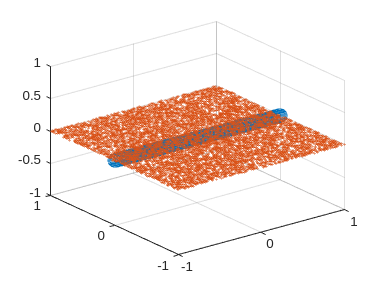

clc
scatter3(NSpts2(1,:),zeros(1,10000),zeros(1,10000),100)
hold on
scatter3(NSpts3(1,:),NSpts3(2,:),zeros(1,10000),1)
hold off

## Q3

M = randi([0 9],3,2)';
M(3,:) = randi([1 3])*M(1,:) + randi([1 3])*M(2,:);
[RR, ic] = rref(M);
RSBV = RR(1:length(ic),:);
CSBV = rref(M')

CSBV =      1     0     3
     0     1     2
     0     0     0


RSpts = gen_points_RS(RSBV)

RSpts =     0.9345   -0.0296    0.0574    0.9725   -0.7522    0.7672    0.5160   -0.3010    0.7734   -0.6934    0.3144    0.9157    0.1065    0.7094   -0.5296   -0.6100   -0.6916    0.9712    0.5187   -0.8445   -0.8936    0.5556   -0.0108   -0.8528    0.4314    0.0187   -0.0750   -0.4535   -0.1937    0.8169   -0.7378    0.8710    0.1637   -0.4091    0.0966   -0.0779   -0.8814   -0.8322    0.7668   -0.4394   -0.8586   -0.2598   -0.7319    0.8810    0.1493    0.0864    0.5742   -0.1033   -0.8171   -0.2388
    0.0122   -0.8544   -0.3759    0.0694    0.1063    0.2401    0.1282   -0.8017   -0.2173   -0.7158   -0.3441    0.1708    0.0305    0.1668    0.2938    0.9666   -0.1254    0.8518   -0.5419    0.3898   -0.2508    0.8484    0.3064    0.9414   -0.1881   -0.9455    0.2542    0.0901   -0.4953    0.0823    0.8564    0.0731   -0.8134   -0.1115    0.7013   -0.6096   -0.1671   -0.0775   -0.2424    0.3779   -0.6221    0.8909    0.4691   -0.1057    0.9668   -0.6056    0.6218   -0.6090   -0.4046 

CSpts = gen_points_CS(CSBV)

CSpts =    -0.5988   -0.9900   -0.8831   -0.4747    0.6244   -0.3306   -0.9885    0.2827   -0.7492    0.0601   -0.0552    0.5447   -0.2809   -0.7352   -0.2080    0.5483    0.4544    0.7779    0.5582    0.4327   -0.2715    0.9344    0.4159   -0.7191    0.7051    0.3330   -0.4514    0.6253   -0.6389    0.5658    0.8304   -0.0865    0.5018   -0.0712    0.1973   -0.9641    0.4511   -0.1739   -0.3337    0.1958    0.5845   -0.4901   -0.3330    0.7124   -0.2251   -0.2333   -0.9998    0.4716   -0.9271   -0.7177
   -0.2551    0.9548    0.4387    0.7075    0.1560    0.0384    0.0348   -0.6842    0.7692   -0.7854    0.1617    0.1759   -0.1481    0.4150    0.4250   -0.5892    0.1335    0.1528    0.8093    0.9989   -0.7059   -0.1637   -0.1938    0.5088    0.3294   -0.1949    0.4037   -0.5661   -0.0848    0.8500    0.0845    0.6074    0.7560   -0.0604    0.0128   -0.0641    0.9812   -0.1698   -0.4885   -0.2492   -0.4170   -0.2519   -0.0751    0.6528   -0.6950   -0.5133   -0.2692   -0.8009   -0.1464 

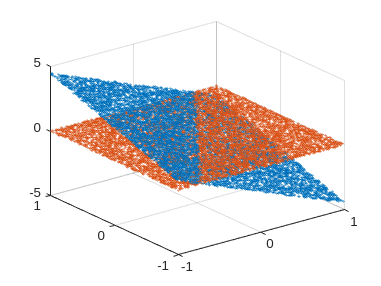

scatter3(RSpts(1,:),RSpts(2,:),RSpts(3,:),1)
hold on
scatter3(CSpts(1,:),CSpts(2,:),CSpts(3,:),1)
hold off

## Q4

M = randi([0 9],3,1)';
M(2,:) = randi([1 3])*M(1,:);
M(3,:) = randi([1 3])*M(1,:) + randi([1 3])*M(2,:);
[RR, ic] = rref(M);
CS = rref(M')

CS =      1     2     3
     0     0     0
     0     0     0


CSpts = gen_points_CS(CS)

CSpts =    -2.0794    0.5529   -1.0792    1.3231   -0.6619    0.3001    0.0825   -0.2279   -1.3560   -2.0937    1.4987    2.1693   -0.1090    1.5412   -1.8233   -0.1081   -0.1756   -0.6937   -1.5830   -0.0413    1.5853   -1.8747    2.2953    0.2409   -0.5316    1.7041   -1.4912   -1.8212    0.6078   -2.2333    2.2665    0.2237   -0.7093   -0.7497    1.5479   -1.1923   -0.7330   -2.1970    2.0463   -1.5360    0.3365   -0.4895   -1.7801    1.2935   -0.5520    0.6709    0.4326   -2.2853   -0.1822    1.6829
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

scatter3(CSpts(1,:),CSpts(2,:),CSpts(3,:),1)
hold on
LNS = null(M)

LNS =    -0.7071         0
    0.7071         0
         0    1.0000


LNSPts = gen_points_CS(LNS)

LNSPts =     0.5521   -0.4098    0.6937    0.6437   -0.3835    0.4515   -0.2358    0.4013   -0.1691    0.5215   -0.4995   -0.2745   -0.6083   -0.0895   -0.5592   -0.2487   -0.5231   -0.0314   -0.3981   -0.1052   -0.1777    0.0501    0.6423   -0.0862    0.1677   -0.6599   -0.6971    0.0688    0.0850    0.1490   -0.6534    0.6398   -0.4351    0.2241    0.1324   -0.3571   -0.3171   -0.3003    0.5748   -0.1230    0.6063    0.1238    0.0632    0.6711   -0.2805    0.0827    0.4516   -0.1449    0.1346    0.6580
   -0.5521    0.4098   -0.6937   -0.6437    0.3835   -0.4515    0.2358   -0.4013    0.1691   -0.5215    0.4995    0.2745    0.6083    0.0895    0.5592    0.2487    0.5231    0.0314    0.3981    0.1052    0.1777   -0.0501   -0.6423    0.0862   -0.1677    0.6599    0.6971   -0.0688   -0.0850   -0.1490    0.6534   -0.6398    0.4351   -0.2241   -0.1324    0.3571    0.3171    0.3003   -0.5748    0.1230   -0.6063   -0.1238   -0.0632   -0.6711    0.2805   -0.0827   -0.4516    0.1449   -0.1346

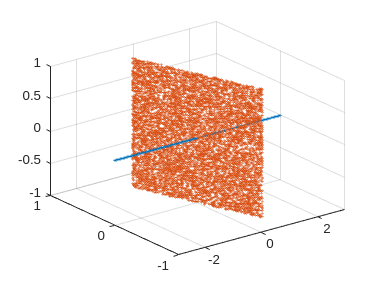

scatter3(LNSPts(1,:),LNSPts(2,:),LNSPts(3,:),1)
hold off

## Q5

A = [1 3 4 7; 2 4 6 10; 3 5 8 13; 4 6 10 16]

A =      1     3     4     7
     2     4     6    10
     3     5     8    13
     4     6    10    16


u = [-2;-3;1;1]

u =     -2
    -3
     1
     1



Check_subspace(A,u)

This lies in null space

v = [5;8;11;14];
Check_subspace(A,v)

This lies in column space

w = [1;1;2;3];
Check_subspace(A,w)

This lies in row space

y = [1;2;0;-1];
Check_subspace(A,y)

This lies in null space

m = [-1;1;1;-1];
Check_subspace(A,m)

## Q6

A=[1 -1 2 3;0 2 1 4;1 1 3 1;2 0 5 4];

v=[5;1;-2;0];
Check_subspace(A,v)

This lies in null space

w=[0;2;2;2];
Check_subspace(A,w)

This lies in column space

u=[-1;2;-1;1];
Check_subspace(A,u)

This does not lie in a subspace

m=[3;-1;7;7];
Check_subspace(A,m)

This lies in row space